# Course Project (MSE 422): Cathode Degradation Analysis

Source: E. Fensterle *et al.*, “Spatially Resolved Electrochemical Characterization of a PEM Fuel Cell Stack During Durability Testing,” *International Journal of Hydrogen Energy*, vol. 250, Art. no. 156060, July 2026, doi: 10.1016/j.ijhydene.2026.156060.

## From the research article

### 1. Lab setup

The study targets the durability of proton exchange membrane fuel cells (PEMFC) for heavy-duty applications, and the need to identify and understand the aging mechanisms.The investigation on the membrane electrode assembly (MEA) is particularly important, since the MEA drives fuel-cell performance degradation during aging. The work focuses on spatially resolved aging effect across the active area, which is done with the CDDM (segmented current-density measurement board) and special expansion boards that transmit the current from the measurement segments to the Zahner device.

Testing condition: Coolant flow was kept constant, chosen so the inlet-to-outlet temperature difference was 10 K at the highest load point (1.8$A/cm^2$)

The test subject is the generic HyFaB stack with an active area of 280 $cm^2$ per cell and a project-specific MEA. Two builds were used: 

- a 10-cell stack for the durability test 

- an 8-cell stack for the BoL EIS sensitivity analysis.

### 2. Testing procedure

A heavy duty load cycle was applied for more than 2000 hours to the stack. At regular intervals the stack was characterized with polarization curves, sensitivity tests, and electrochemical impedance spectroscopy (EIS) at cell level and spatially resolved. The full characterization sequence (after break-in, which aims to reach full cell performance) consisted of six polarization curves at different operating conditions, the partial sensitivity test, EIS at cell level and spatially resolved, and cyclic voltammetry.

Polarization curves were measured at 16 load points from 0 to 1.8 $A/cm^2$, in both descending and ascending order. The minimum current for stoichiometric operation was 0.3 $A/cm^2$ for the durability test and 0.5 $A/cm^2$ for the full sensitivity test. Sensitivity tests study the influence of operating conditions on performance, including temperature, humidity, pressure, and stoichiometry, at four different current densities.

EIS is a powerful method for separating the resistances of transport, conduction, and reaction processes, which occur at different frequencies. Both cell and spatially resolved impedance were measured galvanostatically. For the cell impedance the AC was 5% of the DC; for the spatially resolved measurements a slightly higher AC gave less noise.

### 3. Result from the research

Cell voltage decrease over time, and the largest jump is between BoL (beginning of life) curve and the curve after 300 hours (25 cycles), about half the total loss happens in the first 300 hours (63.3 $\mu V/h$). The degradation rate at 1.8 $A/cm^2
$ is 15.7 $\mu V/h$ overall; excluding the reversible loss (comparing the after-air/air-start curves) it drops to 13.0 $\mu V/h$, and about 2.7 $\mu V/h$ of the loss is reversible.

Degradation impact increases with decreasing pressure, especially in the resistance of the oxygen reduction reaction (ORR). Temperature, humidity and stoichiometry variations did not show a strong influence of aging; the aging effect on sensitivity becomes evident under varying pressure. Increasing operating pressure enhances reactant availability and cell operation (as at BoL), but with a much more beneficial effect after aging: higher partial pressure improves oxygen transport to the catalyst layer, mitigating the impact of aging and supporting more uniform, robust performance. Aging effects are strongest at low pressures and elevated temperatures. Heterogeneity of the current-density distribution decreases with increasing humidity, pressure and stoichiometry, but increases with temperature. Mass-transport resistance is most strongly affected by stoichiometry, with pronounced increases in the outlet region at low stoichiometric ratios.

The active area is divided into 27 columns in the flow direction and averaged per column. Over time there is a visible shift of the current-density maximum toward the cathode inlet; the inhomogeneity increases and the maximum reaches higher values after 2300 hours. At the lowest load, local current densities at the air inlet become even lower, compensated by higher values in the middle; at higher loads there is no air-inlet effect, but an increased slope between the maximum (near the air inlet) and the middle-outlet area. Degradation therefore has a greater influence on the current-density distribution at lower temperatures (and at low stoichiometry).

The impedance spectra were interpreted through three points read off the Nyquist plot. The high-frequency resistance (HFR) is the ohmic loss: mainly the membrane (proton-transport) resistance, with smaller contributions from electronic contact resistances and electrode-related effects such as ionomer distribution and possible swelling. The low-frequency resistance (LFR) is the sum of all losses. The two arcs between the HFR, intermediate-frequency (IFR) and LFR intercepts correspond to two processes: ORR charge transfer on the cathode in the intermediate-frequency range, and mass transport in the low-frequency range. These were fitted with an equivalent circuit in which R₀ is the membrane resistance and the charge-transfer and mass-transport steps are each an R-CPE element.

Across the 2300 h test, the membrane held up well. Its resistance rose only slightly, with a clearer jump after 1150 hours, consistent with chemical aging of the membrane (radical attack that lowers proton conductivity) and possibly a small rise in interfacial contact resistance (e.g. between the gas-diffusion layer and the bipolar plate). Because this increase was small, the ohmic term changed little overall, and aging produced only minor effects in the average cell-level impedance.

The dominant degradation was on the cathode. The ORR charge-transfer resistance increased over time, driven by catalyst aging (Pt particle growth, dissolution and agglomeration, and carbon-support corrosion) that reduces the electrochemically active surface area (ECSA), with the loss concentrated in the cathode outlet region. The mass-transport resistance, which would normally grow as gas-diffusion paths become blocked (liquid-water accumulation, loss of GDL hydrophobicity, pore-structure changes, carbon-support corrosion), instead stayed roughly constant; the authors attribute this to the test avoiding high potentials and possibly being too short to trigger those mechanisms. In short, catalyst degradation mainly affected the ECSA and therefore the charge-transfer resistance, while the ohmic/membrane resistance remained largely unaffected.

## For this project

### 1. Aim of this project

<Plan: redo some analysis on the datasets on degradation effects, use the timestamps as the main reference for time, the aim is to build a regression model that can estimate the degradation effect, and testing out with optimal controller MPC, if time permits> 

### 2. Methodologies

### 3. Analysis

clear; clc; close all
here = "C:\Users\dangs\Desktop\project\fuel_cell_project\Cathode Degradation of PEMFC";
if isempty(here), here = pwd; end
dataDir = fullfile(here, 'MATLAB');
outDir  = fullfile(here, 'results');
if ~exist(outDir, 'dir'), mkdir(outDir); end

%% 0. Settings
P.R = 8.314; P.F = 96485; P.P0 = 101.325;      % J/mol/K, C/mol, kPa
P.N = 10; P.A = 280;                           % cells, active area per cell (cm^2)
P.Ea = 80;            % kJ/mol, ORR activation energy (fixed, see section 2)
P.jx = exp(-6);       % A/cm^2, crossover-equivalent current (fixed, ~2.5 mA/cm^2)
P.tau = 300;          % h, time constant of the fast early degradation (half the loss in the first 300 h)

% balance of plant
P.T_amb = 298.15;     % K, compressor inlet
P.eta_is = 0.70;      % compressor isentropic efficiency
P.eta_mot = 0.90;     % motor + inverter efficiency
P.dp_hum = 5;         % kPa, humidifier + piping drop added to the measured stack drop (assumed)
P.dp_coef = [0.1495 0.00164];   % stack cathode drop: dp = a*Q + b*Q^2 (kPa, Q in L/min actual), fitted to p.Si.C - p.So.C
P.F_cl = 6.0;         % L/min coolant flow (polarization-curve setting)
P.dp_cl = 47.5;       % kPa coolant drop at 6 L/min (measured), scaled with flow^2
P.eta_pump = 0.5;
P.RH_a = 0.50;        % anode inlet humidity referenced to coolant inlet (measured median)
P.lam_a = 1.5;  P.dpa = 10;     % anode stoichiometry, anode-cathode pressure offset (kPa)
P.T_max = 80;         % degC, upper limit on mean cell temperature (highest measured: 79 degC)

% decision variables x = [p_c (kPaG), lambda_c (-), T_in (degC), RH_c (-)]
% bounds = the range covered by the sensitivity tests; the model is not trusted outside it
lb = [ 50, 1.6, 55, 0.30];
ub = [200, 2.1, 75, 0.90];
x_nom = [150, 1.7, 70, 0.35];
xnames = {'p_c_kPaG', 'lambda_c', 'T_in_C', 'RH_c'};

%% 1. Data
H = readtable(fullfile(dataDir, 'holds.csv'));
A = readtable(fullfile(dataDir, 'hfr_anchor.csv'));
TP = readtable(fullfile(dataDir, 'thermal_params.csv'));
tp = containers.Map(TP.name, num2cell(TP.value));
P.th_T = [tp('a'), tp('b_flow'), tp('c_j2'), tp('d_Tin'), tp('e_age')];

% fit set: loaded holds, no air/air-start curves, no shutdown hold (22 kPaG)
keep = H.air_air_start == 0 & H.j > 0.02 & H.p_c > 40;
d = struct();
for c = {'j','U','p_c','p_a','lambda_c','lambda_a','dpt_c','dpt_a','T_cin','T_mean','RH','age_h'}
    d.(c{1}) = H.(c{1})(keep);
end
d.dataset = H.dataset(keep);  d.parameter = H.parameter(keep);
isSens = strcmp(d.dataset, 'sensitivity');
fprintf('Fit set: %d holds (%d polarization, %d sensitivity)\n', numel(d.j), sum(~isSens), sum(isSens));

Fit set: 435 holds (286 polarization, 149 sensitivity)



%% 2. Voltage model
% U = E_Nernst - eta_act - eta_ohm - eta_mt
%   E_Nernst  from T, pH2 (anode) and the log-mean O2 partial pressure along the cathode channel
%   eta_act = RT/(alpha F) * [ ln((j + jx)/j0) - gamma ln(pO2/P0) ],  j0 = exp(lnj0 + aging) * Arrhenius(Ea)
%   eta_ohm = j * HFR(age, j) * (RH/0.35)^(-nu)              HFR from Tier-1 EIS (not fitted here)
%   eta_mt  = c * (1 + aging) * exp(-kT (T - 343 K)) * (j / (pO2/P0))^m
% aging: fast term (1 - exp(-t/tau)) plus a slow linear term (t/1000 h), on both j0 and the transport loss
%
% Ea is fixed at 80 kJ/mol: a free fit (~100 kJ/mol) overstates the temperature slope at low load and
% understates it at high load (the polarization curves cannot separate kinetic from transport
% temperature effects, because cell temperature rises with load). 80 kJ/mol matches the low-load
% slope; the high-load temperature benefit is then underestimated by about half (conservative).

% 2a. HFR(age, j) from the nominal cell spectra
an = strcmp(A.source, 'cell_nominal');
Xh = [ones(sum(an),1), A.age_h(an)/1000, A.j(an)];
P.hb = Xh \ A.HFR(an);
fprintf('HFR = %.4f + %.4f*age_kh + %.4f*j  (Ohm cm^2)\n', P.hb);

HFR = 0.0483 + 0.0018*age_kh + 0.0038*j  (Ohm cm^2)



% 2b. fit (weights: sensitivity holds x2, they carry the operating-condition slopes the optimizer uses)
pnames = {'lnj0','j0_fast','j0_slow','alpha','gamma','nu','lnc','m','c_fast','c_slow','kT'};
th0 = [-15, -0.3, -0.05, 1.0, 0.4, 0.2, -6.5, 1.8, 0.1, 0.05, 0.03];
thl = [-40,   -5,   -5,  0.2, 0.0, 0.0, -12, 1.0,  -1,  -1, -0.3];
thu = [  0,    5,    5,  2.0, 1.5, 1.5,   0, 6.0,   5,   5,  0.3];
sc = max(abs(th0), 0.1);                         % parameter scaling
w = ones(numel(d.j),1);  w(isSens) = 2;
resfun = @(p) w .* (Vcell(p.*sc, P, d.j, d.T_mean+273.15, d.p_c, d.p_a, d.lambda_c, d.lambda_a, ...
                          d.dpt_c, d.dpt_a, d.RH, d.age_h) - d.U);
optsL = optimoptions('lsqnonlin', 'Display', 'off', 'MaxFunctionEvaluations', 2e4, ...
                     'MaxIterations', 2e3, 'FunctionTolerance', 1e-12, 'StepTolerance', 1e-12);
[p_fit, ~, ~, exitflag, ~, ~, Jac] = lsqnonlin(resfun, th0./sc, thl./sc, thu./sc, optsL);
P.th = p_fit .* sc;

U_fit = Vcell(P.th, P, d.j, d.T_mean+273.15, d.p_c, d.p_a, d.lambda_c, d.lambda_a, d.dpt_c, d.dpt_a, d.RH, d.age_h);
r = U_fit - d.U;
Jth = full(Jac) ./ sc;                            % Jacobian w.r.t. physical parameters
se = sqrt(diag(inv(Jth'*Jth)) * sum((w.*r).^2)/(numel(r) - numel(P.th)));
fprintf('\nVoltage model (lsqnonlin exitflag %d): RMSE %.2f mV over %d holds\n', exitflag, 1e3*sqrt(mean(r.^2)), numel(r));


Voltage model (lsqnonlin exitflag 1): RMSE 4.32 mV over 435 holds


disp(table(P.th(:), se(:), 'RowNames', pnames, 'VariableNames', {'value','std_err'}))

                value       std_err 
               ________    _________

    lnj0        -13.656      0.19473
    j0_fast    -0.49344     0.051442
    j0_slow    0.080137     0.023881
    alpha       0.97404     0.015077
    gamma       0.40809     0.043498
    nu           0.1985     0.012472
    lnc         -6.9859      0.12941
    m            2.0241      0.05596
    c_fast     0.089736      0.12853
    c_slow      0.23362     0.056295
    kT         0.011666    0.0018312




% error by test group
key = strcat(d.dataset, '_', arrayfun(@(a) sprintf('%04d', a), d.age_h, 'UniformOutput', false), '_', d.parameter);
[gname, ~, grp] = unique(key);
gr = accumarray(grp, r, [], @(v) 1e3*sqrt(mean(v.^2)));
gb = accumarray(grp, r, [], @(v) 1e3*mean(v));
disp(table(gname, gr, gb, 'VariableNames', {'group','rmse_mV','bias_mV'}))

                 group                  rmse_mV     bias_mV 
    ________________________________    _______    _________

    {'polarization_0000_none'      }    4.7001       0.27584
    {'polarization_0300_none'      }    4.5647       0.01571
    {'polarization_0600_none'      }    4.4436      -0.97664
    {'polarization_0850_none'      }     4.461      -0.96282
    {'polarization_1150_none'      }    4.3358        1.1607
    {'polarization_1500_none'      }    4.0506       0.24054
    {'polarization_1750_none'      }    4.1329       0.90693
    {'polarization_2000_none'      }    4.5626        2.0744
    {'polarization_2300_none'      }    4.6956        1.5461
    {'sensitivity_0000_Humidity'   }    4.7907        -0.549
    {'sensitivity_0000_Pressure'   }    3.9638       -2.1883
    {'sensitivity_0000_Stoic'      }    3.9796      -0.37146
    {'sensitivity_0000_Temperature'}     5.

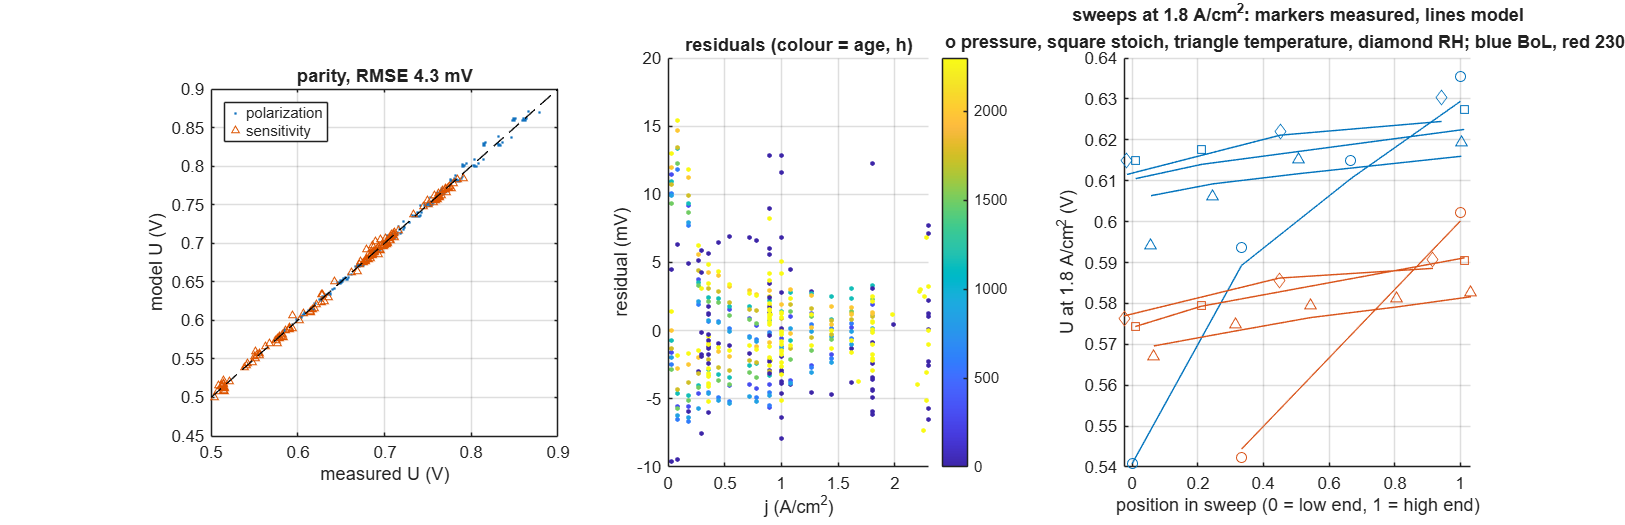


% 2c. figures: parity, and the sensitivity sweeps at 1.8 A/cm^2 (the slopes the optimizer relies on)
f1 = figure('Name', 'Voltage model', 'Position', [80 80 1300 420]);
subplot(1,3,1)
plot(d.U(~isSens), U_fit(~isSens), '.', d.U(isSens), U_fit(isSens), '^', 'MarkerSize', 4); hold on
plot([0.5 0.9], [0.5 0.9], 'k--'); grid on; axis square
xlabel('measured U (V)'); ylabel('model U (V)'); legend('polarization', 'sensitivity', 'Location', 'northwest')
title(sprintf('parity, RMSE %.1f mV', 1e3*sqrt(mean(r.^2))))
subplot(1,3,2)
scatter(d.j, 1e3*r, 8, d.age_h, 'filled'); grid on; colorbar
xlabel('j (A/cm^2)'); ylabel('residual (mV)'); title('residuals (colour = age, h)')
subplot(1,3,3); hold on; grid on
swp = {'Pressure','p_c',[50 200]; 'Stoic','lambda_c',[1.6 2.1]; 'Temperature','T_cin',[55 75]; 'Humidity','RH',[0.3 0.9]};
mk = {'o','s','^','d'};
for k = 1:4
    for age = [0 2300]
        s = isSens & strcmp(d.parameter, swp{k,1}) & abs(d.j - 1.8) < 0.05 & d.age_h == age;
        xv = d.(swp{k,2})(s);
        [xv, o] = sort((xv - swp{k,3}(1)) / diff(swp{k,3}));      % normalized 0..1 along each sweep
        um = d.U(s); up = U_fit(s);
        col = [0 0.45 0.74]; if age == 2300, col = [0.85 0.33 0.10]; end
        plot(xv, um(o), mk{k}, 'Color', col, 'HandleVisibility', 'off');
        plot(xv, up(o), '-', 'Color', col, 'HandleVisibility', 'off');
    end
end
xlabel('position in sweep (0 = low end, 1 = high end)'); ylabel('U at 1.8 A/cm^2 (V)')
title({'sweeps at 1.8 A/cm^2: markers measured, lines model', 'o pressure, square stoich, triangle temperature, diamond RH; blue BoL, red 2300 h'})
print(f1, fullfile(outDir, 'fig_voltage_model.png'), '-dpng', '-r130');


%% 3. System model at the nominal point
for age = [0 2300]
    s0 = fcSystem(x_nom, 1.8, age, P);
    fprintf('Nominal @1.8 A/cm^2, %4d h: U %.3f V, T_cell %.1f C, P_stack %.0f W, P_comp %.0f W, P_net %.0f W, eta_sys %.3f\n', ...
            age, s0.U, s0.T_cell, s0.P_stack, s0.P_comp, s0.P_net, s0.eta_sys);
end

Nominal @1.8 A/cm^2,    0 h: U 0.615 V, T_cell 73.6 C, P_stack 3098 W, P_comp 482 W, P_net 2606 W, eta_sys 0.413
Nominal @1.8 A/cm^2, 2300 h: U 0.580 V, T_cell 73.3 C, P_stack 2923 W, P_comp 482 W, P_net 2432 W, eta_sys 0.385



%% 4. Single operating point: fmincon (multistart) vs fminsearch
optsF = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off', ...
                     'OptimalityTolerance', 1e-10, 'StepTolerance', 1e-10, 'ConstraintTolerance', 1e-8);
optsS = optimset('Display', 'off', 'TolX', 1e-9, 'TolFun', 1e-10, 'MaxFunEvals', 6000, 'MaxIter', 6000);
starts = [x_nom; (lb+ub)/2; lb + 0.15*(ub-lb); lb + 0.85*(ub-lb); ...
          [lb(1) ub(2) lb(3) ub(4)]; [ub(1) lb(2) ub(3) lb(4)]];
j_pt = 1.8;
cmp = [];
for age = [0 2300]
    obj = @(x) negPnet(x, j_pt, age, P);                          % -P_net in kW, minimized
    con = @(x) tempCon(x, j_pt, age, P);                          % T_cell <= T_max
    % fmincon from several starts
    best = struct('x', x_nom, 'f', inf);  nfe = 0;  tic
    for k = 1:size(starts,1)
        [xk, fk, ef, out] = fmincon(obj, starts(k,:), [], [], [], [], lb, ub, con, optsF);
        nfe = nfe + out.funcCount;
        if ef >= 0 && fk < best.f, best = struct('x', xk, 'f', fk); end
    end
    tF = toc;
    % fminsearch: bounds through x = lb + (ub-lb).*(1+sin(z))/2, temperature limit as a penalty
    z2x = @(z) lb + (ub - lb) .* (1 + sin(z)) / 2;
    pen = @(x) obj(x) + 1e3 * max(0, tempCon(x, j_pt, age, P))^2;
    tic; [zs, fs, ~, outS] = fminsearch(@(z) pen(z2x(z)), asin(2*(x_nom - lb)./(ub - lb) - 1), optsS); tS = toc;
    xs = z2x(zs);
    s0 = fcSystem(x_nom, j_pt, age, P); sF = fcSystem(best.x, j_pt, age, P); sS = fcSystem(xs, j_pt, age, P);
    cmp = [cmp; age, x_nom, s0.P_net, s0.P_comp, s0.U, NaN, NaN; ...
                age, best.x, sF.P_net, sF.P_comp, sF.U, nfe, tF; ...
                age, xs, sS.P_net, sS.P_comp, sS.U, outS.funcCount, tS]; %#ok<AGROW>
end
method = repmat({'nominal'; 'fmincon (6 starts)'; 'fminsearch'}, 2, 1);
T4 = array2table(cmp, 'VariableNames', [{'age_h'}, xnames, {'P_net_W','P_comp_W','U_V','fun_evals','time_s'}]);
T4 = addvars(T4, method, 'Before', 1);
fprintf('\nOptimum at %.1f A/cm^2:\n', j_pt); disp(T4)


Optimum at 1.8 A/cm^2:
            method            age_h    p_c_kPaG    lambda_c    T_in_C    RH_c    P_net_W    P_comp_W      U_V      fun_evals     time_s 
    ______________________    _____    ________    ________    ______    ____    _______    ________    _______    _________    ________

    {'nominal'           }       0         150       1.7         70      0.35    2606.2      482.12     0.61464       NaN            NaN
    {'fmincon (6 starts)'}       0      192.68       1.6         75       0.9    2690.2      523.06     0.63944       862        0.17083
    {'fminsearch'        }       0      192.68       


%% 5. Load sweep: optimal setpoints vs current density and age (fmincon, warm-started)
jv = (0.4:0.1:2.0)';
ages = [0 1150 2300];
rows = [];
for age = ages
    x0 = x_nom;
    for jj = jv'
        obj = @(x) negPnet(x, jj, age, P);
        con = @(x) tempCon(x, jj, age, P);
        best = struct('x', x0, 'f', inf);
        for xs0 = [x0; x_nom; (lb+ub)/2]'
            [xk, fk, ef] = fmincon(obj, xs0', [], [], [], [], lb, ub, con, optsF);
            if ef >= 0 && fk < best.f, best = struct('x', xk, 'f', fk); end
        end
        x0 = best.x;
        so = fcSystem(best.x, jj, age, P);  sn = fcSystem(x_nom, jj, age, P);
        rows = [rows; age, jj, best.x, so.U, so.T_cell, so.P_stack, so.P_comp, so.P_net, so.eta_sys, ...
                sn.U, sn.P_comp, sn.P_net, sn.eta_sys]; %#ok<AGROW>
    end
end
M = array2table(rows, 'VariableNames', [{'age_h','j'}, xnames, {'U','T_cell','P_stack','P_comp','P_net','eta_sys', ...
                                         'U_nom','P_comp_nom','P_net_nom','eta_sys_nom'}]);
M.gain_pct = 100 * (M.P_net ./ M.P_net_nom - 1);
writetable(M, fullfile(outDir, 'opt_map.csv'));
% which variables end up on a bound: those are limited by the trusted data range, not by a trade-off
tol = 1e-3 * (ub - lb);
X = [M.p_c_kPaG, M.lambda_c, M.T_in_C, M.RH_c];
fprintf('\nShare of load points where the optimum sits on a bound:\n');


Share of load points where the optimum sits on a bound:


for k = 1:4
    fprintf('  %-9s lower %3.0f %%   upper %3.0f %%   interior %3.0f %%\n', xnames{k}, ...
            100*mean(X(:,k) <= lb(k) + tol(k)), 100*mean(X(:,k) >= ub(k) - tol(k)), ...
            100*mean(X(:,k) > lb(k) + tol(k) & X(:,k) < ub(k) - tol(k)));
end

  p_c_kPaG  lower  20 %   upper  24 %   interior  57 %
  lambda_c  lower 100 %   upper   0 %   interior   0 %
  T_in_C    lower   0 %   upper 100 %   interior   0 %
  RH_c      lower   0 %   upper  51 %   interior  49 %


fprintf('\nNet-power gain over the nominal setpoint (%%):\n');


Net-power gain over the nominal setpoint (%):


disp(array2table(reshape(M.gain_pct, numel(jv), numel(ages)), ...
     'VariableNames', arrayfun(@(a) sprintf('age_%dh', a), ages, 'UniformOutput', false), ...
     'RowNames', arrayfun(@(v) sprintf('j=%.1f', v), jv, 'UniformOutput', false)))

             age_0h    age_1150h    age_2300h
             ______    _________    _________

    j=0.4    4.4515     4.3492       4.2221  
    j=0.5    4.2001     3.9928       3.7918  
    j=0.6     3.873     3.5333       3.2394  
    j=0.7    3.4664     2.9918       2.6767  
    j=0.8    3.0207     2.5464       2.2596  
    j=0.9     2.668     2.2242       1.9788  
    j=1.0    2.4122     2.0182       1.8277  
    j=1.1    2.2484     1.9242       1.8025  
    j=1.2    2.1738     1.9395       1.8968  
    j=1.3    2.1833     2.0481       2.0908  
    j=1.4    2.2592     2.2412       2.3848  
    j=1.5    2.3998     2.5211       2.7822  
    j=1.6    2.6064     2.8907  

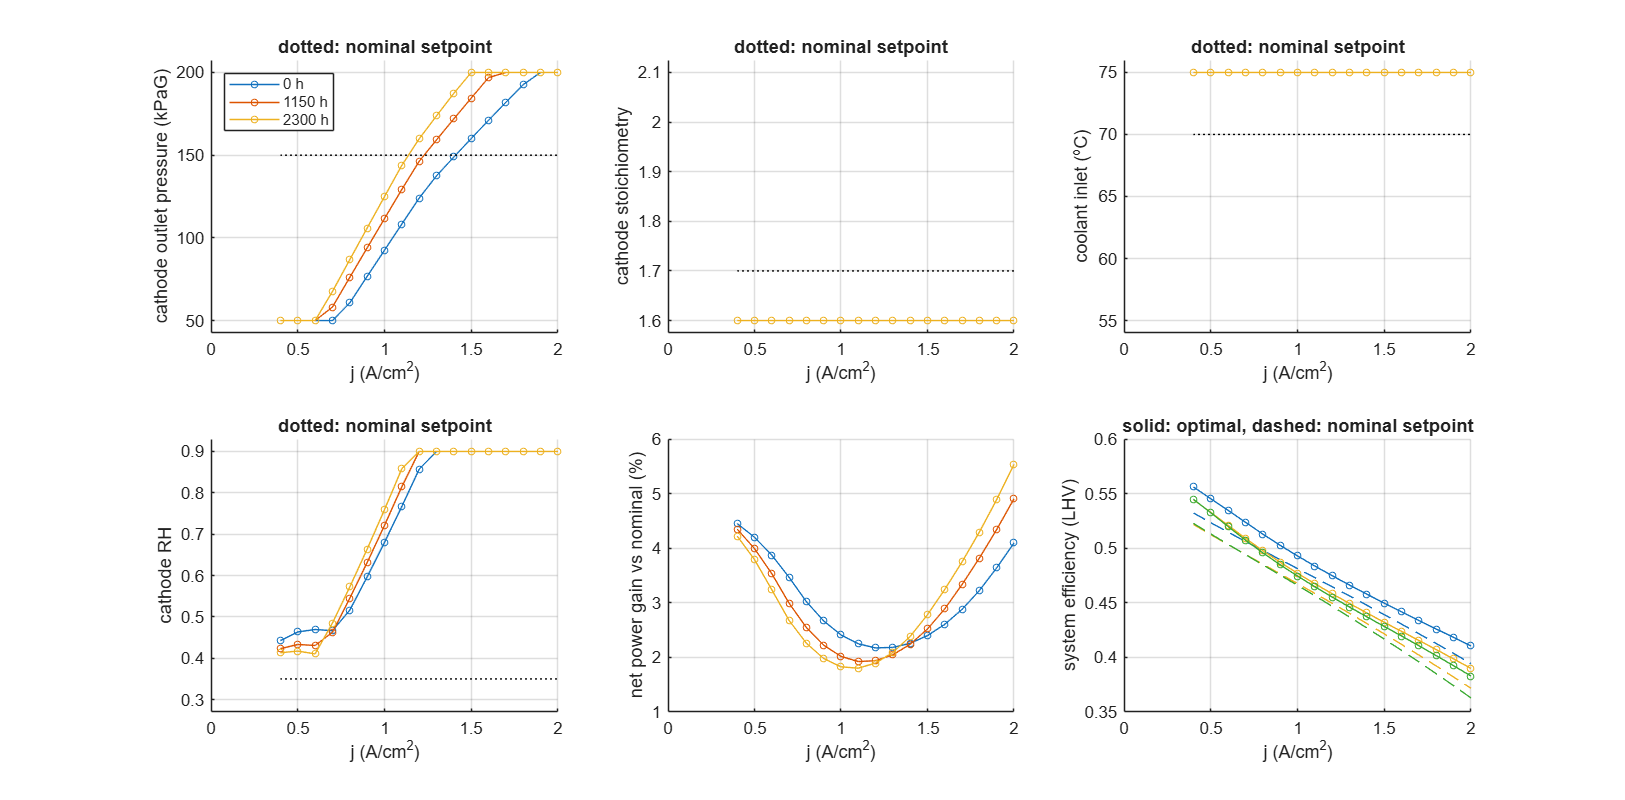


f2 = figure('Name', 'Optimal setpoints', 'Position', [80 80 1300 640]);
lab = {'cathode outlet pressure (kPaG)', 'cathode stoichiometry', 'coolant inlet (^oC)', 'cathode RH', ...
       'net power gain vs nominal (%)', 'system efficiency (LHV)'};
for k = 1:6
    subplot(2,3,k); hold on; grid on
    for age = ages
        s = M.age_h == age;
        switch k
            case {1,2,3,4}, y = M.(xnames{k})(s);
            case 5, y = M.gain_pct(s);
            case 6, y = M.eta_sys(s);
        end
        hl = plot(M.j(s), y, '-o', 'MarkerSize', 4, 'DisplayName', sprintf('%d h', age));
        if k == 6, plot(M.j(s), M.eta_sys_nom(s), '--', 'Color', get(hl, 'Color'), 'HandleVisibility', 'off'); end
    end
    if k <= 4, plot(jv([1 end]), x_nom([k k]), 'k:', 'HandleVisibility', 'off'); end
    if k == 6, title('solid: optimal, dashed: nominal setpoint'); end
    if k <= 4, title('dotted: nominal setpoint'); ylim([lb(k) ub(k)] + [-0.05 0.05]*(ub(k) - lb(k))); end
    xlabel('j (A/cm^2)'); ylabel(lab{k});
    if k == 1, legend('Location', 'northwest'); end
end
print(f2, fullfile(outDir, 'fig_optimal_setpoints.png'), '-dpng', '-r130');

%% 6. Save for the Monte Carlo study (step 3)
settings = struct('lb', lb, 'ub', ub, 'x_nom', x_nom, 'xnames', {xnames}, 'pnames', {pnames}, 'th_se', se(:)');
save(fullfile(outDir, 'voltage_model.mat'), 'P', 'settings', 'M', 'T4');
fprintf('\nSaved: %s\n', outDir);


Saved: C:\Users\dangs\Desktop\project\fuel_cell_project\Cathode Degradation of PEMFC\results


function U = Vcell(th, P, j, T, pc, pa, lam, lama, dptc, dpta, RH, age_h)
    % Cell voltage (V). j A/cm^2, T K, pressures kPaG, dew points degC, RH referenced to coolant inlet.
    [E, act, ohm, mt] = vparts(th, P, j, T, pc, pa, lam, lama, dptc, dpta, RH, age_h);
    U = E - act - ohm - mt;
end

function [E, act, ohm, mt] = vparts(th, P, j, T, pc, pa, lam, lama, dptc, dpta, RH, age_h)
    lnj0 = th(1); j0f = th(2); j0s = th(3); alpha = th(4); gam = th(5); nu = th(6);
    lnc = th(7); m = th(8); cf = th(9); cs = th(10); kT = th(11);
    gf = 1 - exp(-age_h / P.tau);  gs = age_h / 1000;
    lam = max(lam, 1.001);
    pO2 = 0.2095 * (pc + P.P0 - psat(dptc)) .* (1./lam) ./ (-log(1 - 1./lam));   % log-mean along channel, kPa
    pH2 = 0.80 * (pa + P.P0 - psat(dpta)) .* (1 - 1./(2*lama));                  % anode feed is 80 % H2
    E = 1.229 - 8.46e-4*(T - 298.15) + P.R*T/(2*P.F) .* log(pH2/P.P0 .* sqrt(pO2/P.P0));
    j0 = exp(lnj0 + j0f*gf + j0s*gs) .* exp(-P.Ea*1e3/P.R * (1./T - 1/343.15));
    act = P.R*T./(alpha*P.F) .* (log((j + P.jx)./j0) - gam*log(pO2/P.P0));
    ohm = j .* (P.hb(1) + P.hb(2)*age_h/1000 + P.hb(3)*j) .* (RH/0.35).^(-nu);
    mt = exp(lnc) * (1 + cf*gf + cs*gs) .* exp(-kT*(T - 343.15)) .* (j ./ (pO2/P.P0)).^m;
end

function f = negPnet(x, j, age_h, P)
    % objective for the minimizers: -P_net in kW
    s = fcSystem(x, j, age_h, P);
    f = -s.P_net / 1e3;
end

function [c, ceq] = tempCon(x, j, age_h, P)
    % nonlinear inequality c <= 0: mean cell temperature below P.T_max
    s = fcSystem(x, j, age_h, P);
    c = s.T_cell - P.T_max;
    ceq = [];
end

function s = fcSystem(x, j, age_h, P)
    % Stack + compressor + coolant pump at operating point x = [p_c kPaG, lambda_c, T_in degC, RH_c].
    pc = x(1); lam = x(2); Tin = x(3); RH = x(4);
    t = P.th_T;                                                   % mean cell temperature model
    T_cell = Tin + t(1) + t(2)*j*6/P.F_cl + t(3)*j^2 + t(4)*(Tin - 70) + t(5)*age_h/1000;
    dptc = dewpoint(RH * psat(Tin));
    dpta = dewpoint(P.RH_a * psat(Tin));
    U = Vcell(P.th, P, j, T_cell + 273.15, pc, pc + P.dpa, lam, P.lam_a, dptc, dpta, RH, age_h);
    I = j * P.A;                                                  % A
    nO2 = P.N * I / (4*P.F);  nair = lam * nO2 / 0.2095;          % mol/s (dry air)
    mair = nair * 0.02897;                                        % kg/s
    Fn = nair * 22.414 * 60;                                      % NL/min
    Pout = pc + P.P0;  dp = 19;
    for it = 1:3                                                  % stack drop at mean channel pressure
        Qv = Fn * P.P0 / (Pout + dp/2) * (Tin + 5 + 273.15) / 273.15;
        dp = P.dp_coef(1)*Qv + P.dp_coef(2)*Qv^2;
    end
    P_cmp_out = Pout + dp + P.dp_hum;
    s.P_comp = mair * 1005 * P.T_amb / (P.eta_is * P.eta_mot) * ((P_cmp_out/P.P0)^(0.4/1.4) - 1);
    s.P_pump = P.dp_cl * (P.F_cl/6)^2 * 1e3 * P.F_cl/60000 / P.eta_pump;
    s.P_stack = P.N * I * U;
    s.P_net = s.P_stack - s.P_comp - s.P_pump;
    s.eta_sys = s.P_net / (P.N * I / (2*P.F) * 241.8e3);          % LHV of H2 consumed
    s.U = U; s.T_cell = T_cell; s.dp_stack = dp;
end

function p = psat(t)
    % saturation pressure of water (Magnus), kPa, t in degC
    p = 0.61094 * exp(17.625 * t ./ (t + 243.04));
end

function t = dewpoint(pv)
    % inverse of psat, degC
    l = log(pv / 0.61094);
    t = 243.04 * l ./ (17.625 - l);
end
